# Examples for using the `interp1_linear` function.

Copyright © 2021 Tamas Kis

## Example #1: Linear interpolation at a single point.

*Linearly interpolate a value for *$\theta$* at *$\psi =5\ldotp 2$* for the following data set (taken from *[*https://www.mathsisfun.com/data/least-squares-regression.html*](https://www.mathsisfun.com/data/least-squares-regression.html)*):*


$$\begin{array}{l}
\psi :2,3,5,7,9\\
\theta :4,5,7,10,15
\end{array}$$


Define the data set.

psi = [2,3,5,7,9];
theta = [4,5,7,10,15];

Interpolate for $\theta$ at $\psi =5\ldotp 2$.

theta_interp = interp1_linear(psi,theta,5.2)

theta_interp = 7.3000

## Example #2: Linear interpolation/extrapolation at multiple points.

*Linearly interpolate/extrapolate values for *$y$* at the *$x$*-values *$x=z_1 ,\ldotp \ldotp \ldotp ,z_q$* where the data set *$y$* vs. *$x$* is*


$$\begin{array}{l}
x:2,3,5,7,9\\
y:4,5,7,10,15
\end{array}$$


*and where the vector *$z$* is*


$$\mathbf{z}=\left\lbrack \begin{array}{c}
0\\
0\ldotp 2\\
0\ldotp 4\\
\vdots \\
10
\end{array}\right\rbrack$$


*Additionally, plot the original as well as the interpolate values on the same plot.*

Let's begin by defining vectors to store the $x$ and $y$ values, as wwell as the vector $\mathbf{z}$.

x = [2,3,5,7,9];
y = [4,5,7,10,15];
z = (0:0.2:10)';

Linearly interpolate values for $y$ at $x=z_1 ,z_2 ,\ldotp \ldotp \ldotp ,z_q$.

y_interp = interp1_linear(x,y,z);

Initialize the figure.

figure;
hold on;

Plot the original points.

plot(x,y,'k.','markersize',30);

Plot the interpolated points.

plot(z,y_interp,'o','markersize',7,'linewidth',1.5);

Format the plot.

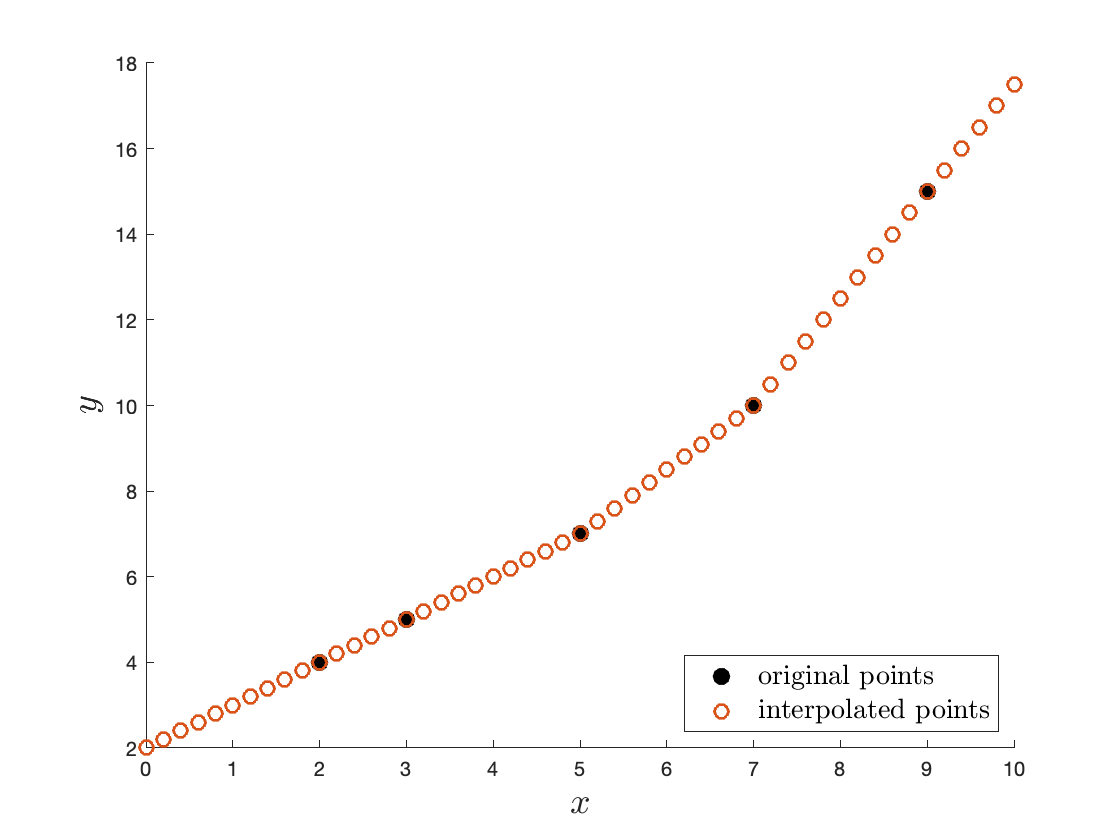

xlabel('$x$','interpreter','latex','fontsize',18);
ylabel('$y$','interpreter','latex','fontsize',18);
legend('original points','interpolated points','interpreter','latex',...
    'fontsize',14,'location','southeast');